## Task_ Session_1

%% NAME: 

##  EEG Analysis Task with Cohen & Ridderinkhof (2013) Dataset

**Goal**: Your objective is to load a single subject's EEG data from the Cohen & Ridderinkhof (2013) dataset, specifically for the **Congruent condition**, and perform a full analysis pipeline to visualize the ERP with confidence intervals.

**Scenario:** The Cohen & Ridderinkhof (2013) dataset investigates the conflict monitoring theory using a Flanker task. You've been provided with a `.mat` file for one subject containing raw EEG data from the Congruent condition. Your task is to process this data to create a clear, publication-quality plot of the average ERP.

**Provided Data:** sampleEEGdata.mat This `.mat` file contains a single MATLAB `struct` named `data`, with the following fields:

- `data.eeg`: A 3D numeric array `[channels x time_points x trials]`

- `data.srate`: The sampling rate in Hz.

- `data.times`: A 1D numeric array of time points in milliseconds.

- `data.chanlocs`: A struct array with channel location information.

**Task Instructions:**

**Part 1: Load, Inspect, and Pre-process (Data Structures & Vectorization)**

- **Load Data:** Load the sampleEEGdata.mat file into your MATLAB workspace.

clear;
clc;
load('sampleEEGdata.mat');   % loads struct called "data"


- **Vectorized Inspection:**

- Use the `size()` function to determine the number of channels, time points, and trials in `data.eeg` without using any loops.

- Display the sampling rate (`data.srate`) and the time vector (`data.times`).

% Get size of the EEG data (channels × time_points × trials)
[eeg_channels, eeg_timepoints, eeg_trials] = size(EEG.data);

% Display sampling rate and time vector
disp(['Sampling rate: ', num2str(EEG.srate), ' Hz']);

Sampling rate: 256 Hz


disp('Time vector (ms):');

Time vector (ms):


disp(EEG.times);

   1.0e+03 *

   -1.0000   -0.9961   -0.9922   -0.9883   -0.9844   -0.9805   -0.9766   -0.9727   -0.9688   -0.9648   -0.9609   -0.9570   -0.9531   -0.9492   -0.9453   -0.9414   -0.9375   -0.9336   -0.9297   -0.9258   -0.9219   -0.9180   -0.9141   -0.9102   -0.9062   -0.9023   -0.8984   -0.8945   -0.8906   -0.8867   -0.8828   -0.8789   -0.8750   -0.8711   -0.8672   -0.8633   -0.8594   -0.8555   -0.8516   -0.8477   -0.8438   -0.8398   -0.8359   -0.8320   -0.8281   -0.8242   -0.8203   -0.8164   -0.8125   -0.8086   -0.8047   -0.8008   -0.7969   -0.7930   -0.7891   -0.7852   -0.7812   -0.7773   -0.7734   -0.7695   -0.7656   -0.7617   -0.7578   -0.7539   -0.7500   -0.7461   -0.7422   -0.7383   -0.7344   -0.7305   -0.7266   -0.7227   -0.7188   -0.7148   -0.7109   -0.7070   -0.7031   -0.6992   -0.6953   -0.6914   -0.6875   -0.6836   -0.6797   -0.6758   -0.6719   -0.6680   -0.6641   -0.6602   -0.6562   -0.6523   -0.6484   -0.6445   -0.6406   -0.6367   -0.6328   -0.6289   -0.6250   -0.6211   -0.

**         3. Extract and Squeeze:** For this task, we will focus on the **Cz channel**, which is typically the 32nd channel in this type of dataset.             

- Using **vectorized indexing**, extract the data for the Cz channel (channel 32) across all time points and all trials.

- Use the `squeeze()` function to remove the singleton dimension, resulting in a 2D array of `[time_points x trials]`. Store this in a new variable, `cz_data_2d`.

% Extract Cz = channel 48, all time points, all trials
cz_data = EEG.data(48, :, :);

% Squeeze to get a [time_points × trials] matrix
cz_data_2d = squeeze(cz_data);  


**        4. Calculate Mean and SEM:**

- Use **vectorized functions** (`mean`, `std`) to calculate the mean ERP of `cz_data_2d` across all trials. Store this as `mean_erp`.

- Calculate the **Standard Error of the Mean (SEM)** using the formula from your notes: SEM=N�std�. Store this as `sem_erp`.

% Mean ERP across trials
mean_erp = mean(cz_data_2d, 2);     % (time_points × 1)

% Standard error of the mean
sem_erp = std(cz_data_2d, 0, 2) / sqrt(size(cz_data_2d, 2));


**Part 2: Visualize the ERP (Data Visualization & Error Bars)**

**        1. Plot ERP with SEM:**

- Ensure you have the `shadedErrorBar.m` function in your MATLAB path.

- Create a new figure.

- Use `shadedErrorBar()` to plot the `mean_erp` with `sem_erp` as the error-bound.

- Choose a clear color for your plot (e.g., `'r'` for red).

**        2. Add Plot Enhancements:**

- Give your plot an informative title: "ERP for Congruent Condition (Cz Channel)".

- Label the x-axis: "Time (ms)".

- Label the y-axis: "Amplitude (μV)".

- Add a vertical line at the stimulus onset (time = 0 ms) to mark the event.

- Add a horizontal line at 0 amplitude to serve as a baseline reference.

- Add a grid to improve readability.

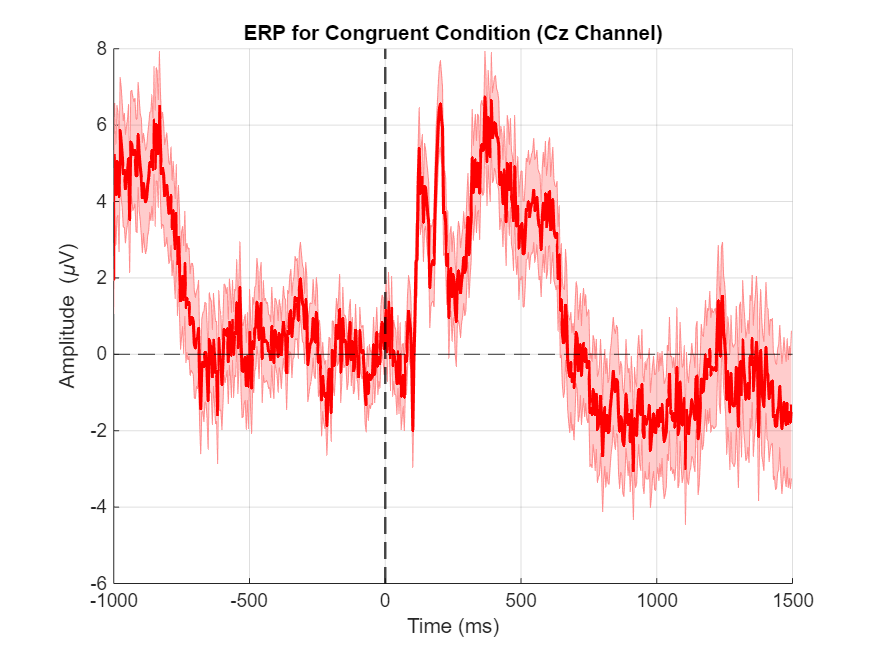

figure;
shadedErrorBar(EEG.times, mean_erp, sem_erp, 'lineprops', {'r', 'LineWidth', 1.5});
hold on;
title('ERP for Congruent Condition (Cz Channel)');
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');

% Vertical line at time = 0 ms (stimulus onset)
xline(0, '--k', 'LineWidth', 1.2);

% Horizontal baseline at amplitude = 0 µV
yline(0, '--k');

grid on;

**Part 3: Debugging and Verification**

As you work, you will practice debugging. Your ERP plot for the Cz channel should have a strong negative peak around 250-350 ms, known as the N200 component. If your plot doesn't show this, you likely have an error.

- **Use **`keyboard`**:**

- Insert `keyboard` into your script right after you calculate `mean_erp` and `sem_erp`.

- Run your script. When the `K>>` prompt appears, check the dimensions and values of `mean_erp` and `sem_erp`. Do they look correct?

         2. **Test small chunks:**

- After extracting `cz_data_2d`, use a simple `plot(cz_data_2d(:, 1))` to verify that a single trial's data looks like an EEG signal.

- If your `shadedErrorBar` plot looks incorrect, try plotting just the mean: `plot(data.times, mean_erp)`. This will help you determine if the issue is in the mean calculation or the error bar visualization.

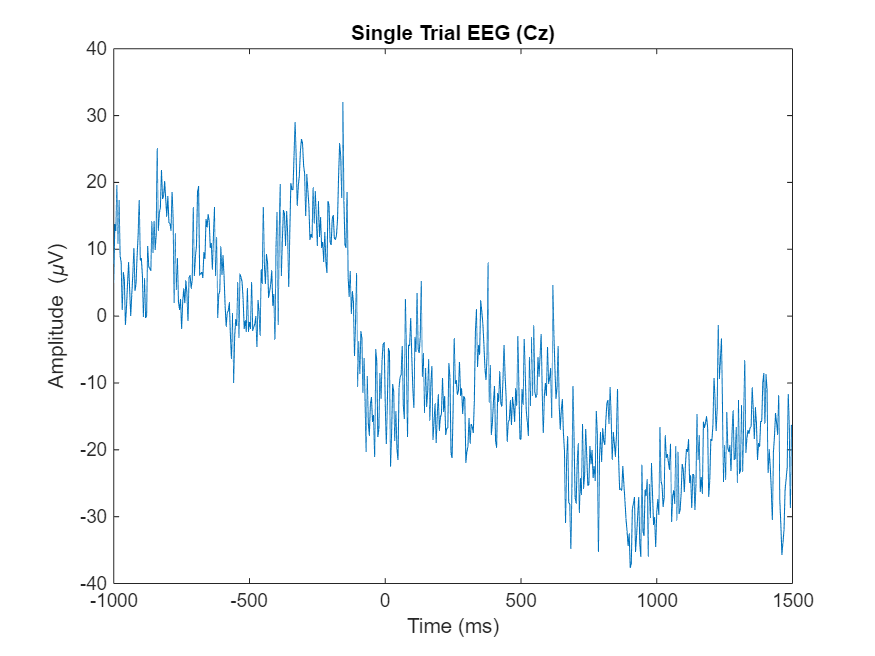

figure;
plot(EEG.times, cz_data_2d(:,1));
title('Single Trial EEG (Cz)');
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');

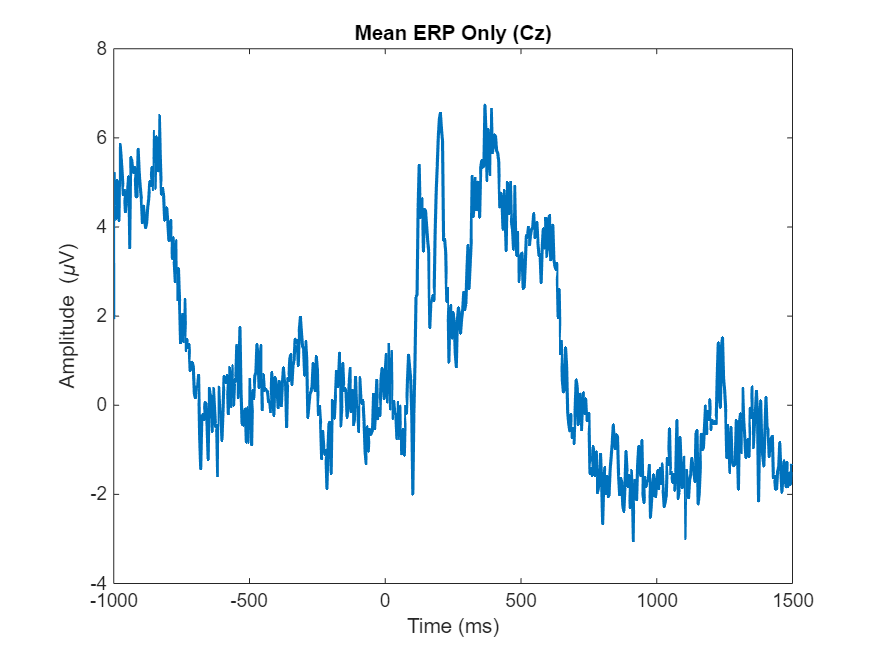

figure;
plot(EEG.times, mean_erp, 'LineWidth', 1.5);
title('Mean ERP Only (Cz)');
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');

        3. **Pre-allocation Check:** Explain in a brief comment in your script why you didn't need to use pre-allocation in this specific task.